filename="meas5.wav";
SDR=audioread(filename);
info = audioinfo(filename)

info = struct with fields:
             Filename: 'C:\Users\Wout\OneDrive - Universiteit Antwerpen\Documenten\Master\1 MAP\Simulation\SNR\Precise SNR FFT\meas5.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 2
           SampleRate: 1000000
         TotalSamples: 136860000
             Duration: 136.8600
                Title: '137.55 MHz, BW 1 MHz, 2023-02-23 12:58'
              Comment: 'Created by DESKTOP-3EC4Q02\Wout on 2023-02-23 12:58:36, filename C:\Users\Wout\OneDrive - Universiteit Antwerpen\Bureaublad\23-Feb-2023 125836.937 137.550MHz.wav'
               Artist: 'SDR-Radio.com, B210 (A:A)'
        BitsPerSample: 32


The number of bins used in the fft is: 4096.000000 
 This results in the following resolution: 244.140625


p = 1.0e-03 *

   0.0185 - 0.0180i
  -0.0010 + 0.0179i
  -0.0219 - 0.0052i
   0.0074 - 0.0484i
   0.0251 - 0.0109i
   0.0022 + 0.0138i
   0.0046 - 0.0128i
   0.0323 - 0.0160i
   0.0110 + 0.0007i
   0.0102 + 0.0100i


The processing gain is 33.113300 dB


value = -125.9448

index = 3069

noisefloor = -145.1590

ENBW = 37.7028

noisefloor = -145.1590

SignaltoNoiseRatio = 19.2142

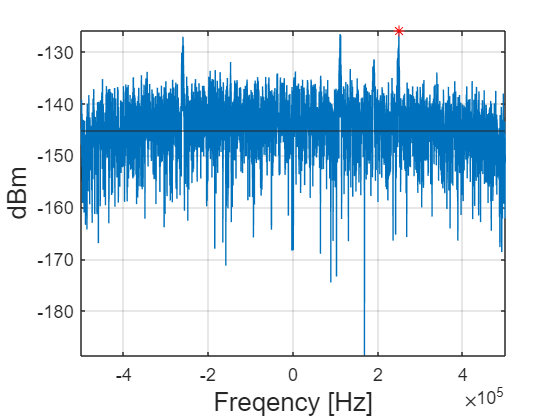

sampleRate= info.SampleRate;
center_freq=137.55; %in MHz
seconds=4;
SDR_snippet=SDR(((seconds-1)*1000000:seconds*1000000),:);

IQData = SDR(:,1)+1i*SDR(:,2);
%IQData=IQData.*hamming(length(IQData))
%plot_FFT_IQ(IQData,1,.01*sampleRate,sampleRate,137.8);
%spectrogram(IQData)
result=Corrected_FFT(IQData,1,0.1*sampleRate,sampleRate,center_freq);

The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


noise_level = 3.5372e-07

ans = -111.5031

value = 1.4507e-05

index = 6115

totalvalue = 4.8014e-07

totalvalue = 1.9417e-06

totalvalue = 3.8031e-06

totalvalue = 9.1699e-06

totalvalue = 9.4795e-06

totalvalue = 1.2871e-05

totalvalue = 1.4823e-05

totalvalue = 1.6341e-05

totalvalue = 2.8279e-05

totalvalue = 3.4312e-05

totalvalue = 4.8819e-05

totalvalue = 5.0646e-05

totalvalue = 5.8321e-05

totalvalue = 5.8782e-05

totalvalue = 6.0971e-05

totalvalue = 6.3280e-05

totalvalue = 6.5051e-05

totalvalue = 6.9192e-05

totalvalue = 7.1098e-05

totalvalue = 7.2974e-05

totalvalue = 7.3007e-05

n = -98.4928

pow = -88.3561

ans = 3.5372e-07

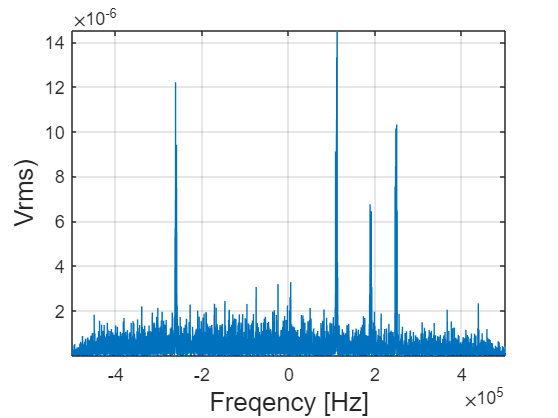


result=Precise_FFT(IQData,1,0.5*sampleRate,sampleRate,center_freq);